data = struct with fields:
    ft: [1.1999e+04 1.1980e+04 1.1999e+04 7.4582e+03 344.8291 1.0705e+04 974.4007 5.8609e+03 1.2000e+04 1.1989e+04 5.5599e+03 5.4614e+03 312.9325 1.2000e+04 6.6671e+03 1.1945e+04 1.1946e+04 1.2000e+04 1.2000e+04 1.1943e+04 1.0367e+04 1.0227e+04 … ]


n = 25

sorted_data = 1.0e+04 *

    0.0313    0.0345    0.0974    0.5461    0.5560    0.5861    0.6667    0.7161    0.7458    1.0227    1.0367    1.0705    1.1171    1.1943    1.1945    1.1946    1.1946    1.1980    1.1989    1.1999    1.1999    1.2000    1.2000    1.2000    1.2000


min_ft = 312.9325

max_ft = 1.2000e+04

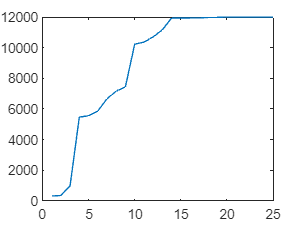

SE = 2.2602e+05

SC = 2.3065e+06

ST = 3.4144e+06

ans = 722.2512

ans = 4.6956e+03

ans = 1.6383e+04

ans = 3.3913e+04

ans = 4.5600e+04

ans = 6.3131e+04

rtci_1 = 15.0051

rtci_2 = 52.3520

rtci_3 = 108.3724

rtci_4 = 145.7193

rtci_5 = 201.7397

clearvars
data = load("failure_times_1.mat");

n = length(data.ft);
sorted_data = sort(data.ft);

min_ft = min(data.ft);
max_ft = max(data.ft);

% plot(1:25, sorted_data)

% natural variation amplitude
w = max_ft - min_ft;

% number of intervals/class
m = round(sqrt(n));

% amplitude of one class
omega = w / (m-1);

% lower limit
u1 = min_ft - omega/2;
% upper limit
umax = max_ft + omega/2;

% find central values and number of values in interval
uci = []; ri = []; index = 1;
for ui = u1:omega:(umax - omega)
    % central values
    uc = (ui + ui + omega) / 2;
    uci(index) = uc;

    % number of values in interval
    a = 0;
    for i = 1:length(data.ft)
        if(data.ft(i) >= ui && data.ft(i) < ui + omega)
            a = a + 1;
        end
    end

    ri(index) = a;
    index = index + 1;
    
end
ni = [0 3 3 9 11];
for i = 1:length(ni)
    nii = ni/n;
end

lambda1 = ri(1)/nii(1) * 5;
lambda2 = ri(2)/nii(2) * 5;
lambda3 = ri(3)/nii(3) * 5;
lambda4 = ri(4)/nii(4) * 5;
lambda5 = ri(5)/nii(5) * 5;